Import the filtered data set

clc;clear;
load("mfcc_mel.mat")

Import filtered data to extract features and labels

AllFeature=MFCCs(:,1)

AllFeature = 920×1 cell 数组
    {26×244 double}
    {26×341 double}
    {26×328 double}
    {26×663 double}
    {26×374 double}
    {26×295 double}
    {26×468 double}
    {26×421 double}
    {26×252 double}
    {26×783 double}
    {26×487 double}
    {26×461 double}
    {26×457 double}
    {26×532 double}
    {26×532 double}
    {26×532 double}


AllLabel=MFCCs(:,2)

AllLabel = 920×1 cell 数组
    {[1]}
    {[1]}
    {[3]}
    {[4]}
    {[2]}
    {[2]}
    {[2]}
    {[2]}
    {[2]}
    {[2]}
    {[1]}
    {[2]}
    {[2]}
    {[2]}
    {[2]}
    {[2]}


AllLabel=cell2mat(AllLabel)

AllLabel = 920×1 int32 列向量
   1
   1
   3
   4
   2
   2
   2
   2
   2
   2


AllLabel=categorical(AllLabel)

AllLabel = 920×1 categorical 数组
     1 
     1 
     3 
     4 
     2 
     2 
     2 
     2 
     2 
     2 
     1 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 


Separate training set and test set

n=randperm(size(AllLabel,1));
TrainFeature=AllFeature(n(1:736))

TrainFeature = 736×1 cell 数组
    {26×269  double}
    {26×499  double}
    {26×941  double}
    {26×1033 double}
    {26×678  double}
    {26×721  double}
    {26×269  double}
    {26×431  double}
    {26×1010 double}
    {26×657  double}
    {26×639  double}
    {26×480  double}
    {26×921  double}
    {26×566  double}
    {26×431  double}
    {26×695  double}


TrainLabel=AllLabel(n(1:736))

TrainLabel = 736×1 categorical 数组
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     3 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     3 
     2 
     2 
     2 
     2 
     2 


TestFeature=AllFeature(n(737:end))

TestFeature = 184×1 cell 数组
    {26×490  double}
    {26×600  double}
    {26×1028 double}
    {26×576  double}
    {26×517  double}
    {26×1205 double}
    {26×775  double}
    {26×754  double}
    {26×507  double}
    {26×656  double}
    {26×507  double}
    {26×385  double}
    {26×450  double}
    {26×663  double}
    {26×451  double}
    {26×832  double}


TestLabel=AllLabel(n(737:end))

TestLabel = 184×1 categorical 数组
     2 
     2 
     2 
     2 
     2 
     2 
     2 
     4 
     2 
     2 
     2 
     2 
     4 
     4 
     2 
     2 
     2 
     2 
     2 
     2 
     1 
     2 
     4 
     2 
     2 
     2 
     2 
     2 
     2 
     2 


Build a deep learning network

**Architecture of a simple LSTM network**

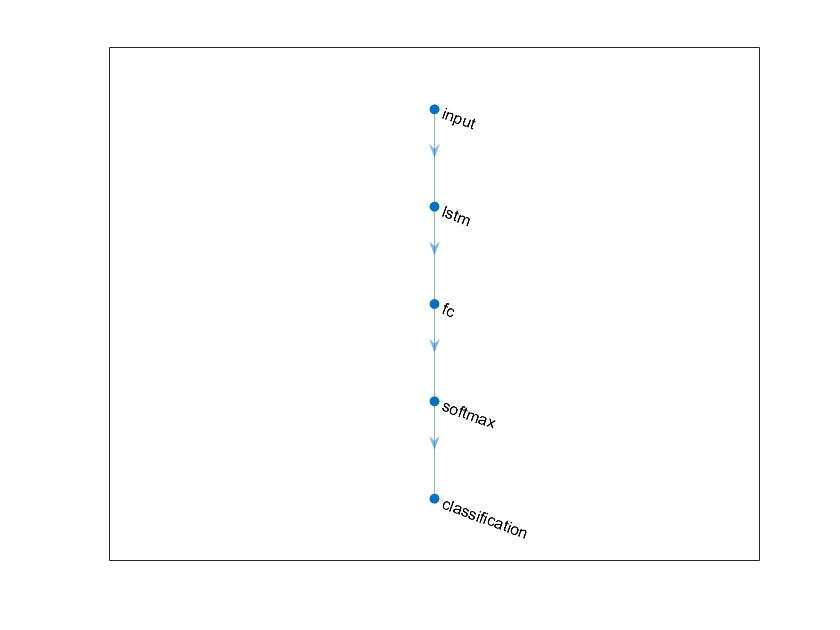

layers = [
    sequenceInputLayer(26,"Name","input")
    lstmLayer(100,"Name","lstm","OutputMode","last")
    fullyConnectedLayer(4,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classification")];
plot(layerGraph(layers));

Train

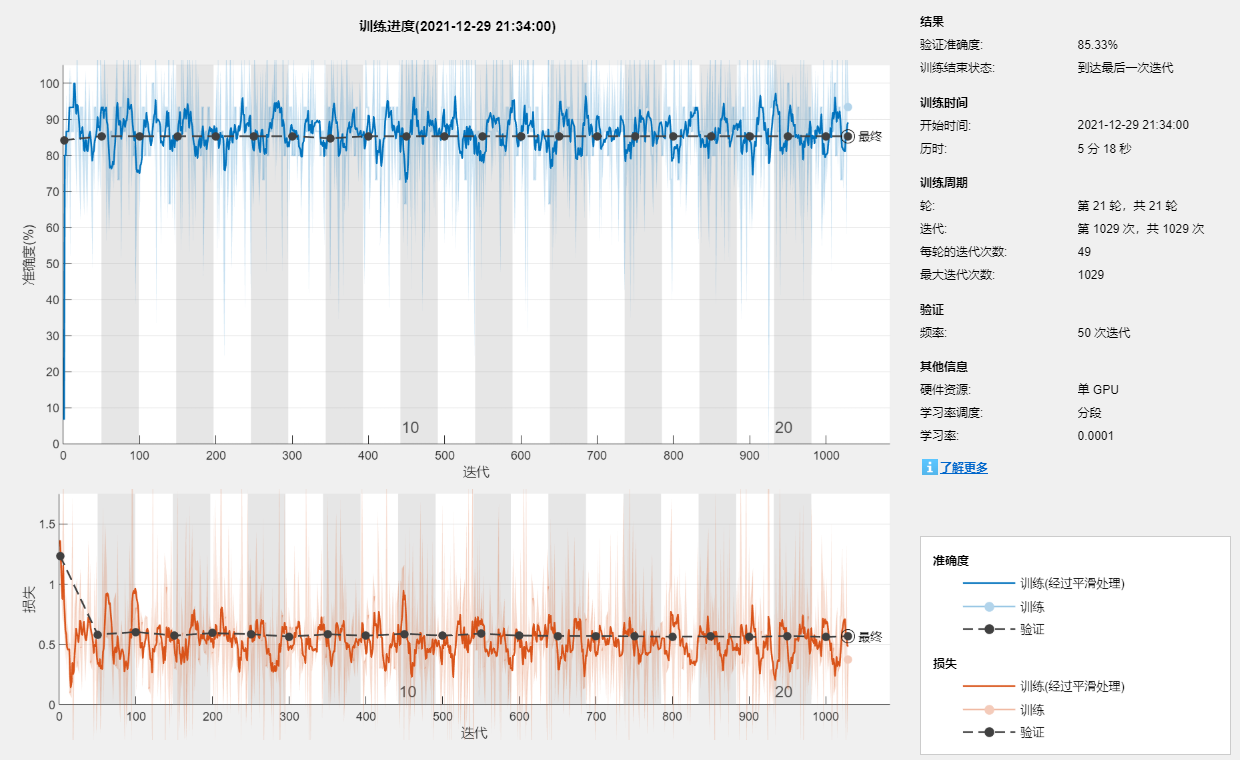

miniBatchSize = 15;
options = trainingOptions('adam', ...
    'InitialLearnRate', 0.0100,...
    'LearnRateSchedule','piecewise', ...
    "LearnRateDropFactor",0.1, ...
    "LearnRateDropPeriod",7, ...
    'ExecutionEnvironment','auto', ...
    'MaxEpochs',21, ...
    'MiniBatchSize',miniBatchSize, ...
    'ValidationData',{TestFeature,TestLabel}, ...
    'GradientThreshold',2, ...
    'Shuffle','every-epoch', ...
    'Verbose',false, ...
    'Plots','training-progress');
net = trainNetwork(TrainFeature,TrainLabel,layers,options);

Calculation accuracy

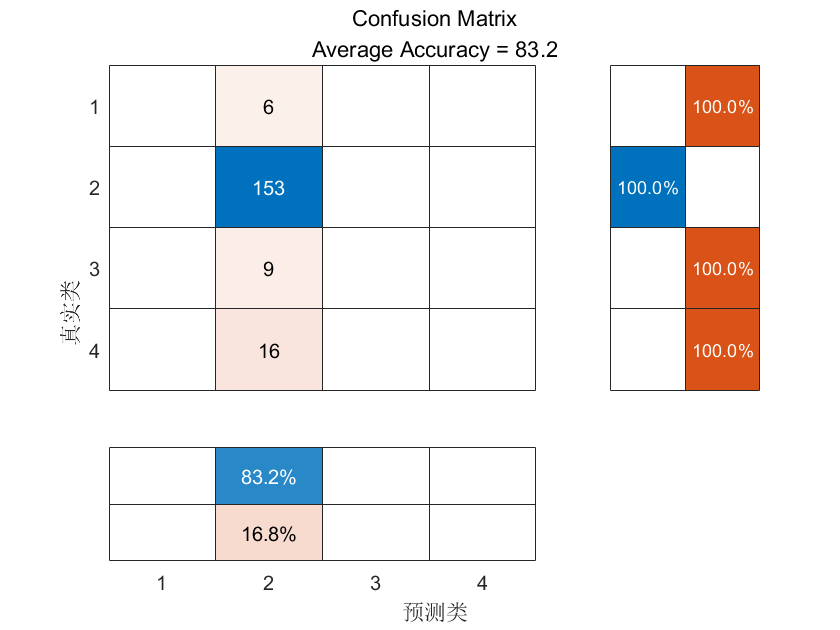

YValPred = classify(net,TestFeature);
valAccuracy = mean(TestLabel==YValPred)*100;
print('Accuracy = %0.1f',valAccuracy)